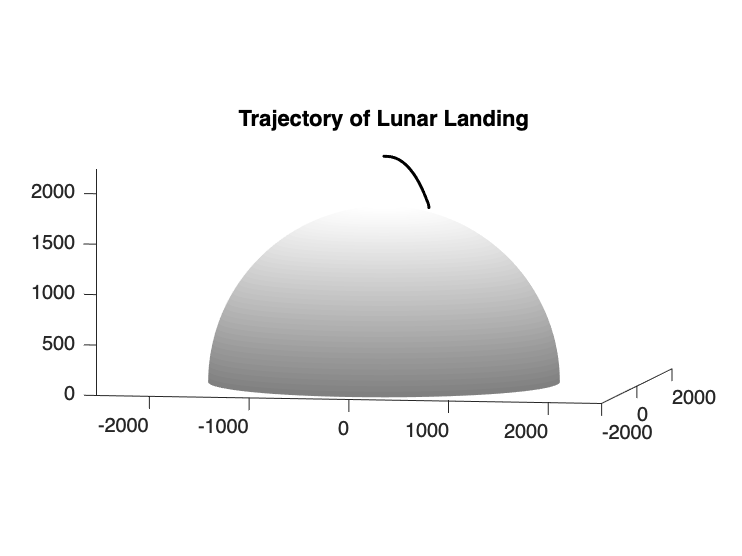

close all; clear, clc
r0= 1737; % radius of moon (km)
load TrajectoryZ.mat % load the trajectory

aRate= 750; % animation plot rate (frame/index)
aPause= 1e-3; % animation pause (s)

% Convert positions to polar
x= x*1e-3;
z= y*1e-3+r0; % radial position
y= zeros(1, length(t)); 

% Plot the trajectory and the Moon
hold on, title("Trajectory of Lunar Landing")
[Xm, Ym, Zm]= sphere(100); % moon surface
Xm= Xm*r0; Ym= Ym*r0; Zm= Zm*r0; 
surf(Xm, Ym, Zm, lineStyle= "none", FaceColor= "flat")
zlim([0, 2250])
colormap gray
axis equal, view([10 5])

for i= 1:length(t)
    if mod(i, aRate)== 1
        plot3(x(i), y(i), z(i), "k.", MarkerSize= 1)
        pause(aPause)
    end
end